% t = [.11, .15, .22, .34, .44, .51, .62, .75, .89, 1];
% s = [.055, .358, .637, 1.073, 1.492, 1.677, 2.181, 2.299, 2.862, 3.1840];
% V = [t.^2 ; t ; 1, 1, 1, 1, 1, 1, 1, 1, 1, 1]'
% c = (inv(V'*V))*(V'*s')
% 
% title("Quadratic Approximation")
% ylabel("y")
% xlabel("t")
% plot(t, s)
% hold on;
% plot(t, -1.1135*t.^2 +4.6043*t - .3565)

t = [-2, -1, 0, 1, 2];
s = [-.2, -.2, .8, 1.6, 3.1];
V = [t.^2; t; 1, 1, 1, 1, 1]'

V =      4    -2     1
     1    -1     1
     0     0     1
     1     1     1
     4     2     1


inv(V'*V)

ans =     0.0714         0   -0.1429
         0    0.1000         0
   -0.1429         0    0.4857


(V'*s')

ans =    13.0000
    8.4000
    5.1000


c = (inv(V'*V))*(V'*s')

c =     0.2000
    0.8400
    0.6200


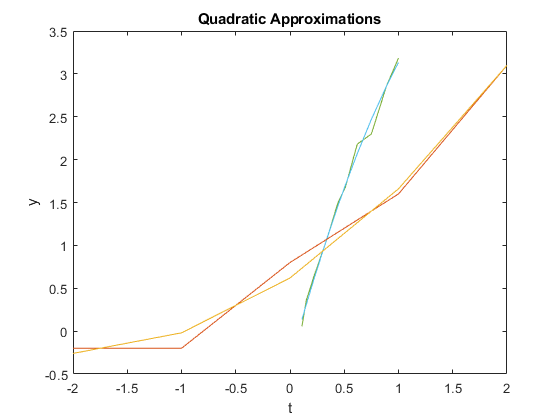


title("Quadratic Approximations")
ylabel("y")
xlabel("t")
plot(t, s)
hold on;
plot(t, .2*t.^2 + .84*t + .62)